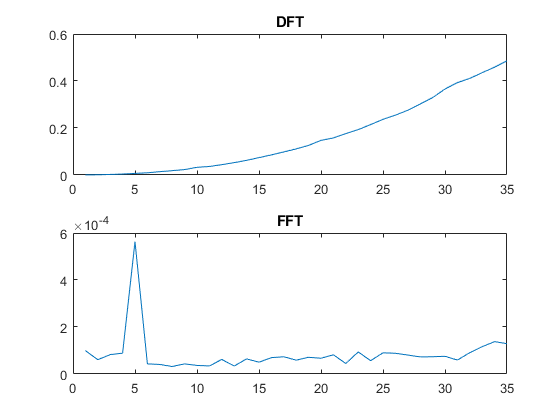


t1=[];
t2=[];
t3=[]; %2N^2
t4=[]; %2Nlog(2)N

for i=1:35
    
    x=0:0.1:i*2;
    y=sin(x);
    N=length(x);
    
    t3(i)=2*N^2;
    t4(i)=N*log2(N);
   
    tic
    mydft(y);
    t1(i)=toc;
    
    tic
    fft(y);
    t2(i)=toc;

end

figure(1)
subplot(2,1,1)
plot(t1);
title('DFT');

subplot(2,1,2)
plot(t2);
title('FFT');

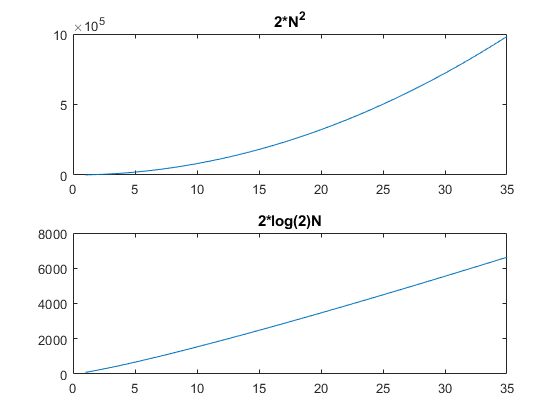


figure(2)
subplot(2,1,1)
plot(t3);
title('2*N^2');
subplot(2,1,2)
plot(t4);
title('2*log(2)N');